%画出Ryy
ny = 7000;
Ryy_y2 = conv(y2, flipud(y2))

Ryy_y2 = 1.0e+04 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


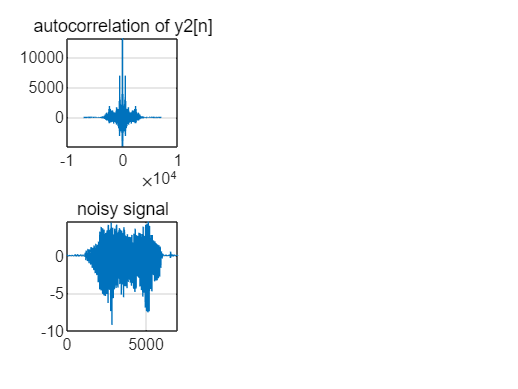


subplot(2, 3, 1);
plot(-ny+1 : ny - 1, Ryy_y2);
grid on;
title('autocorrelation of y2[n]');

subplot(2, 3, 4);
plot(0 : ny-1, y2);
grid on;
title('noisy signal');
hold on;

%通过算Ryy得到N = 500
N = 500;
Rxx = conv(z, flipud(z)); %干净信号的Rxx

Rxx0 = Rxx(ny);
Rxx_N = Rxx(ny + N);
Ryy0 = Ryy_y2(ny);

alpha1 = (-2 * Rxx_N + sqrt((2 * Rxx_N)^2 - 4 * Rxx0 * (Rxx0-Ryy0))) / 2 / Rxx0;
alpha2 = (-2 * Rxx_N - sqrt((2 * Rxx_N)^2 - 4 * Rxx0 * (Rxx0-Ryy0))) / 2 / Rxx0;

disp(alpha1);

    0.6868



disp(alpha2);

   -0.9338



a_y2 = [1, zeros(1, N - 1), alpha1];
x2 = filter(1, a_y2, y2); %还原y2为x2
sound(x2);
Rxx_x2 = conv(x2, flipud(x2));

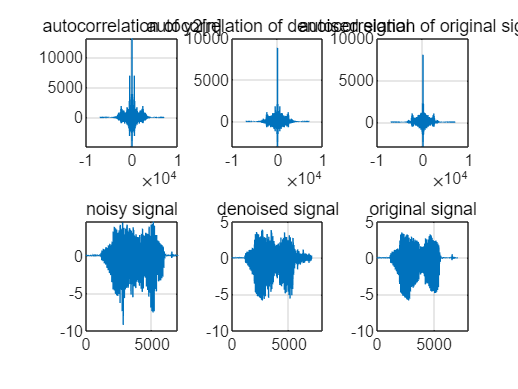

subplot(2, 3, 2);
plot(-ny+1 : ny-1, Rxx_x2);
grid on;
title('autocorrelation of denoised signal');

subplot(2, 3, 3);
plot(-ny+1 : ny-1, Rxx);
grid on;
title('autocorrelation of original signal');

subplot(2, 3, 5);
plot(0 : ny-1, x2);
grid on;
title('denoised signal');
axis([0, 8000, -10, 5]);

subplot(2, 3, 6);
plot(0 : ny-1, z);
grid on;
title('original signal');
axis([0, 8000, -10, 5]);